# Sample 12-2

## 画像復元

フィルタ補正逆投影法 (FBP)

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Image restoration

Filtered backprojection (FBP)

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all

### パラメータ設定

(Parameter settings)

nSlices = 180;
lambda = 10^-5

lambda = 1.0000e-05

## 断層スライス画像の生成

(Creation of tomographic slice images)

- $u(\mathbf{p}), \mathbf{p}\in\mathbb{R}^2$: 原画像 (Original image)

PHANTOM関数を利用して改良型シェップ ローガン頭部ファントム画像 $\mathbf{u}$ を作成して表示 (Create the modified Shepp-Logan head phantom image by using function PHATOM and display it.)

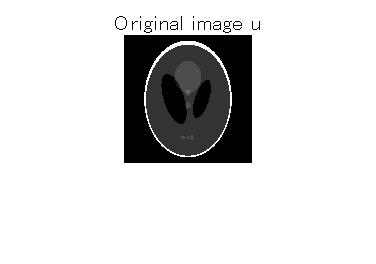

u = phantom(128); 
figure(1)
imshow(u)
title('Original image u')

#### 2変量DFT 

(Bivariate DFT)

        
$$U[\mathbf{k}]=U(e^{j\mathbf{\omega}^T})|_{\mathbf{\omega}=2\pi\mathbf{Q}^{-T}\mathbf{k}$$


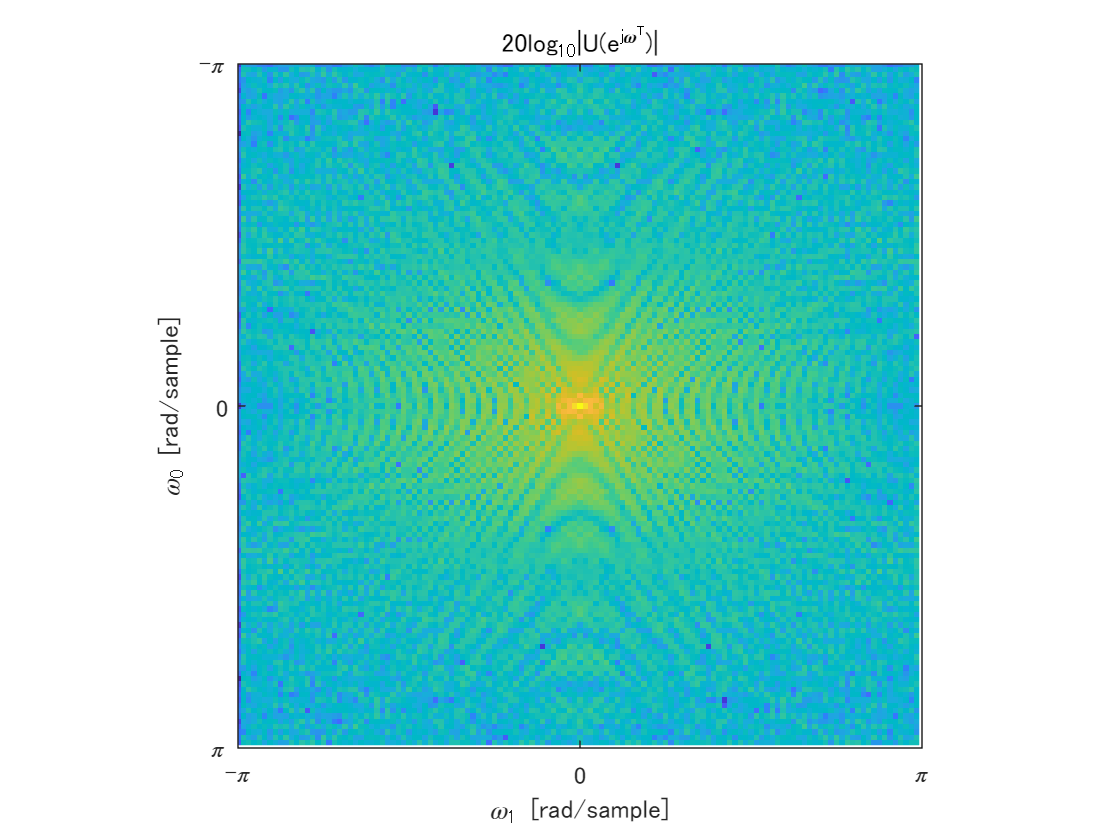

nPointsQ = 2.^nextpow2(size(u));
U = fftn(u,nPointsQ);
figure(2)
w0 = linspace(-pi,pi-2*pi/nPointsQ(2),nPointsQ(2));
w1 = linspace(-pi,pi-2*pi/nPointsQ(1),nPointsQ(1));
imagesc(w1,w0,fftshift(20*log10(abs(U))));
axis square
ylabel('\omega_0 [rad/sample]')
xlabel('\omega_1 [rad/sample]')
title('20log_{10}|U(e^{j{\bf\omega}^T})|')
ax = gca;
ax.YLim = [-pi pi];
ax.XLim = [-pi pi];
ax.YTick = [-pi 0 pi];
ax.YTickLabel = { '-\pi', '0', '\pi'};
ax.XTick = [-pi 0 pi];
ax.XTickLabel = { '-\pi', '0', '\pi'};

### ラドン変換

(Radon transform)

        
$$\mathrm{r}_{u}(x, \theta)=\int_{\mathbb{R}} u\left(x {\bf \theta}+y {\bf \theta}^{\perp}\right) d y$$


ただし，(where)

- 
$$\mathbf{\theta}=(\cos \theta, \sin \theta)^{T}$$


- 
$$\mathbf{\theta}^{\perp}=(-\sin \theta, \cos \theta)^{T}$$


RADON関数を利用 (Use function RADON)

thetaset = linspace(0,180-180/nSlices,nSlices);
[r,p] = radon(u,thetaset);

サイノグラムの表示 (Show sinogram)

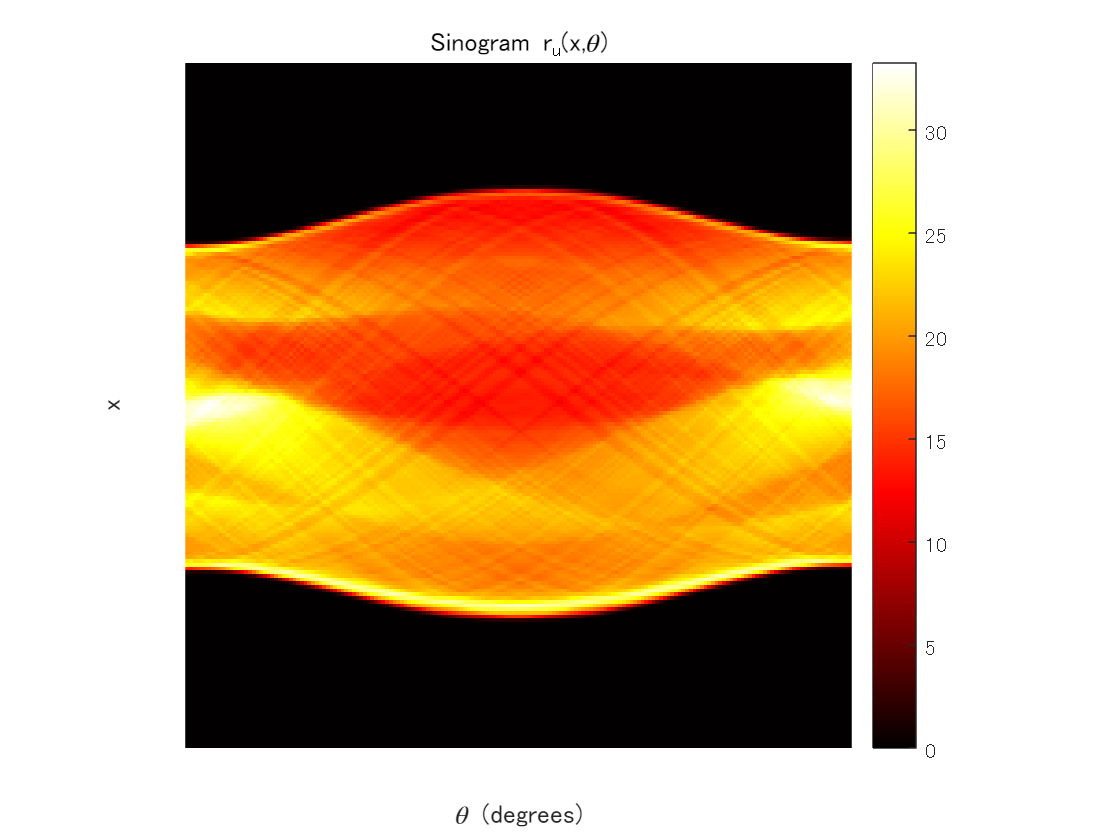

figure(3)
imshow(r,[],'Xdata',thetaset,'Ydata',p,'InitialMagnification','fit')
xlabel('\theta (degrees)')
ylabel('x')
title('Sinogram r_u(x,\theta)')
colormap(gca,hot), colorbar

iptsetpref('ImshowAxesVisible','off')

### スライスの単変量DFT

(Univariate DFT of each slice)

中央スライス定理(Central slice theorem)

        
$$R_u(j\Omega_x,\theta)=U(j(\sin\theta\ \cos\theta)^T\Omega_x)$$


※座標を垂直, 水平の順序で表示していることに注意 (NOTE that  the coordinates are shown in vertical and horizontal order.)

DFTでの解釈 (Interpretation as DFT)

        
$$R_{u,\theta}[k]=R_u(e^{j\omega},\theta)|_{\omega=2\pi k/N}=U(e^{j\mathbf{\omega}^T})|_{\mathbf{\omega}=\left(\begin{array}{c}\sin\theta \\ \cos\theta\end{array}\right)2\pi k/N$$


nPoints = 2^nextpow2(max([size(U,1) length(p)]));
rc = circshift(padarray(r,nPoints-size(r,1),'post'),p(1));
R = fft(rc,nPoints,1);

スライス毎のスペクトルの表示 (Display of spectra for each slice)

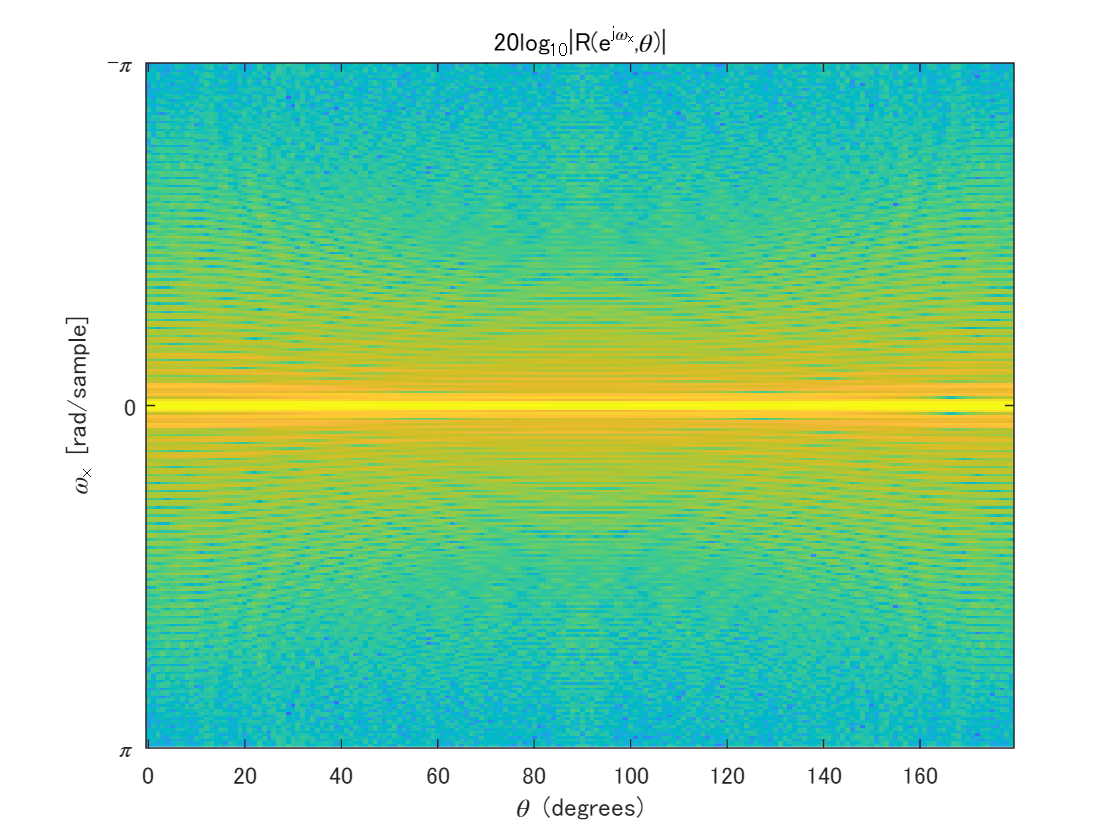

figure(4)
wx = linspace(-pi,pi-2*pi/nPoints,nPoints);
imagesc(thetaset,wx,fftshift(20*log10(abs(R)),1))
ylabel('\omega_x [rad/sample]')
xlabel('\theta (degrees)')
title('20log_{10}|R(e^{j\omega_x},\theta)|')
ax = gca;
ax.YLim = [-pi pi];
ax.YTick = [-pi 0 pi];
ax.YTickLabel = { '-\pi', '0', '\pi'};

iptsetpref('ImshowAxesVisible','off')

### 逆ラドン変換

(Inverse radon transform)

#### 問題設定 (Problem setting)

        
$$\hat{\mathbf{u}}=\arg\min_\mathbf{u}\frac{1}{2}\left\|
\left(\begin{array}{c}\mathbf{r}_{\theta_0} \\
\mathbf{r}_{\theta_1} \\
\vdots \\
\mathbf{r}_{\theta_{I-1}} 
\end{array}\right)
-
\left(\begin{array}{c}
\mathbf{W}_1^{-1}\mathbf{S}_{\downarrow\theta_0} \\
\mathbf{W}_1^{-1}\mathbf{S}_{\downarrow\theta_1}  \\
\vdots \\
\mathbf{W}_1^{-1}\mathbf{S}_{\downarrow\theta_{I-1}} 
\end{array}\right)
\mathbf{W}_2\mathbf{u}
\right\|_2^2
+
\frac{\lambda}{2}\|\mathbf{\nabla}\mathbf{u}\|_2^2$$


ただし，(where)

- $\mathbf{u}\in\mathbb{R}^N$: Vectorized expression of discretized array of $u(\mathbf{p})$ 

- $\mathbf{r}_{\theta_i}\in\mathbb{R}^m$: Vectorized expression of discretized slice line of $r_u(x,\theta)$

- $\mathbf{W}_d$: $d$-dimensional DFT matrix

- $\mathbf{S}_{\downarrow\theta_i}$: Slice operator for direction $\theta_i$

- $\mathbf{\nabla}$: Gradient operator

#### 解 (Solution)

        
$$\widehat{\mathbf{u}}=\mathbf{W}_{2}^{-1}\left(\left(\sum_{i=0}^{I-1} \mathbf{S}_{\downarrow \theta_{i}}^{T} \mathbf{S}_{\downarrow \theta_{i}}\right)+\frac{m}{N} \lambda \mathbf{W}_{2} \mathbf{\nabla}^{T} \mathbf{\nabla W}_{2}^{-1}\right)^{-1}\left(\sum_{i=0}^{I-1} \mathbf{S}_{\downarrow \theta_{i}}^{T} \mathbf{W}_{1} \mathbf{r}_{\theta_{i}}\right)$$


        
$$\stackrel{\mathrm{DFT}}{\longleftrightarrow} \mathrm{U}[\mathbf{k}]=\left(S_{\uparrow \downarrow}[\mathbf{k}]+\frac{m}{N} \lambda\left(\left|\mathrm{G}_{0}[\mathbf{k}]\right|^{2}+\left|\mathrm{G}_{1}[\mathbf{k}]\right|^{2}\right)\right)^{-1}\left(\sum_{i=0}^{I-1} \mathrm{R}_{\theta_{i}}[\mathbf{k}]\right)$$


- $G_0[\mathbf{k}]$: DFT of 1st-order difference filter in vertical direction

- $G_1[\mathbf{k}]$: DFT of 1st-order difference filter in horizontal direction

% Accumuration of backprojected spectrum Rθi[k]
SR = zeros(nPoints+1);
% Accumuration of slice lines in frequency domain
SS = zeros(nPoints+1);
% Zero array
S0 = zeros(nPoints+1);
S1 = S0;
S1(1,:) = 1;
for iSlice = 1:length(thetaset)
    theta = thetaset(iSlice);
    Si = S0;
    Si(1,:) = [R(:,iSlice).' 0];
    SR = SR + imrotate(fftshift(Si),theta,'crop');
    SS = SS + imrotate(fftshift(S1,1),theta,'crop');
end
SR = ifftshift(SR(1:end-1,1:end-1));
SS = ifftshift(SS(1:end-1,1:end-1));

累積スライスラインの表示 (Display accumulated slice lines)

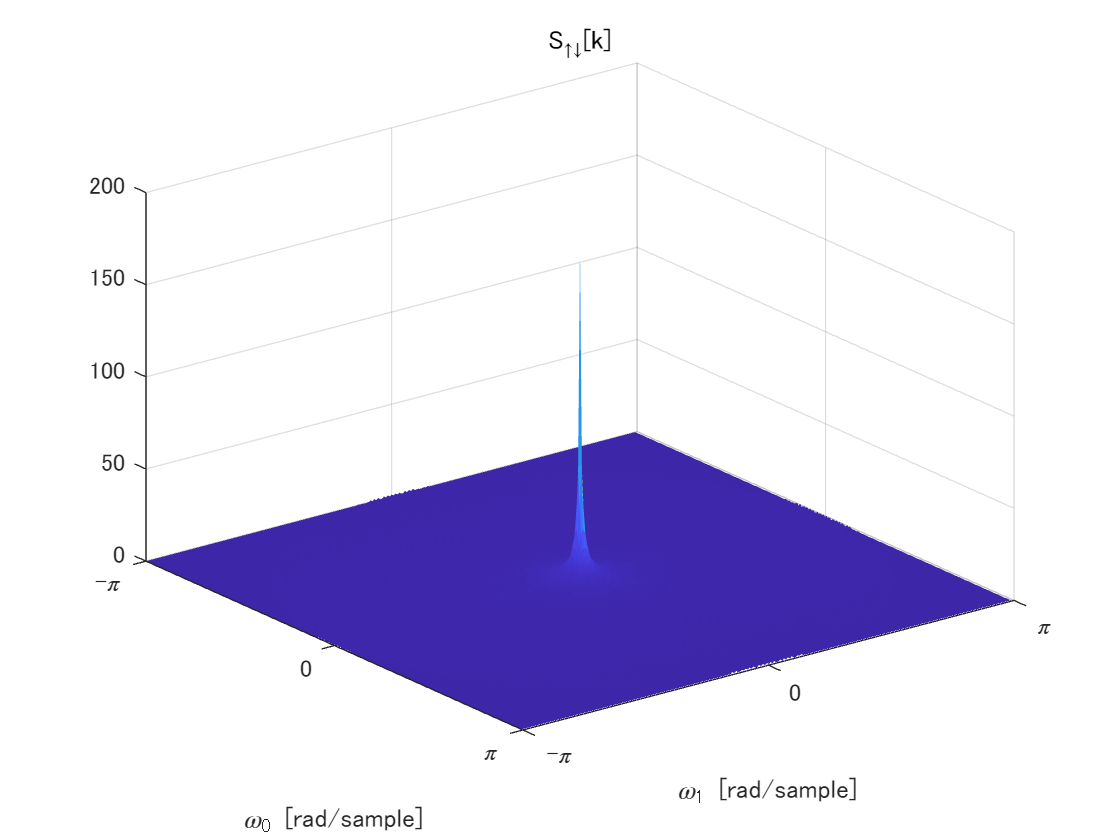

figure(5)
[k0,k1] = ndgrid(linspace(-pi,pi-2*pi/nPoints,nPoints));
surf(k0,k1,fftshift(SS),'EdgeColor','none')
ylabel('\omega_0 [rad/sample]')
xlabel('\omega_1 [rad/sample]')
title('S_{\uparrow\downarrow}[{\bfk}]')
ax = gca;
ax.YDir = 'reverse';
ax.YLim = [-pi pi];
ax.XLim = [-pi pi];
ax.YTick = [-pi 0 pi];
ax.YTickLabel = { '-\pi', '0', '\pi'};
ax.XTick = [-pi 0 pi];
ax.XTickLabel = { '-\pi', '0', '\pi'};

逆投影スペクトルの表示 (Display of backprojected spectrum)

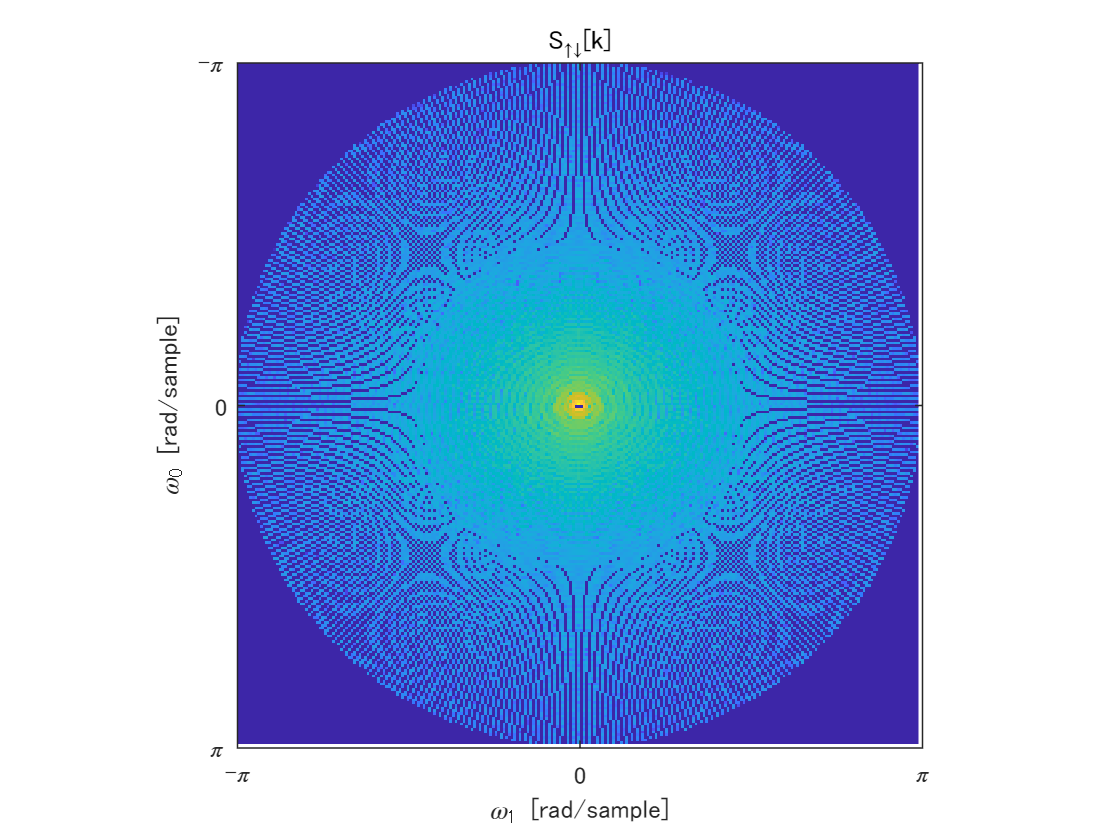

figure(6)
imagesc(w0,w1,fftshift(20*log10(abs(SR))))
axis square
ylabel('\omega_0 [rad/sample]')
xlabel('\omega_1 [rad/sample]')
title('S_{\uparrow\downarrow}[{\bfk}]')
ax = gca;
ax.YDir = 'reverse';
ax.YLim = [-pi pi];
ax.XLim = [-pi pi];
ax.YTick = [-pi 0 pi];
ax.YTickLabel = { '-\pi', '0', '\pi'};
ax.XTick = [-pi 0 pi];
ax.XTickLabel = { '-\pi', '0', '\pi'};

iptsetpref('ImshowAxesVisible','off')

#### 勾配フィルタのパワースペクトル 

(Power spectrum of gradient filter)

        
$$\mathbf{\nabla}^T\mathbf{\nabla}\stackrel{\mathrm{DFT}}{\longleftrightarrow} \left|\mathrm{G}_{0}[\mathbf{k}]\right|^{2}+\left|\mathrm{G}_{1}[\mathbf{k}]\right|^{2}$$


ソーベルフィルタを利用 (Adopt Sobel filter)

g0 = fspecial('sobel');
g1 = g0.';
GG = abs(fftn(g0,nPoints*[1 1])).^2+abs(fftn(g1,nPoints*[1 1])).^2;
LL = nPoints*GG;

パワースペクトルの表示 (Display the power spectrum)

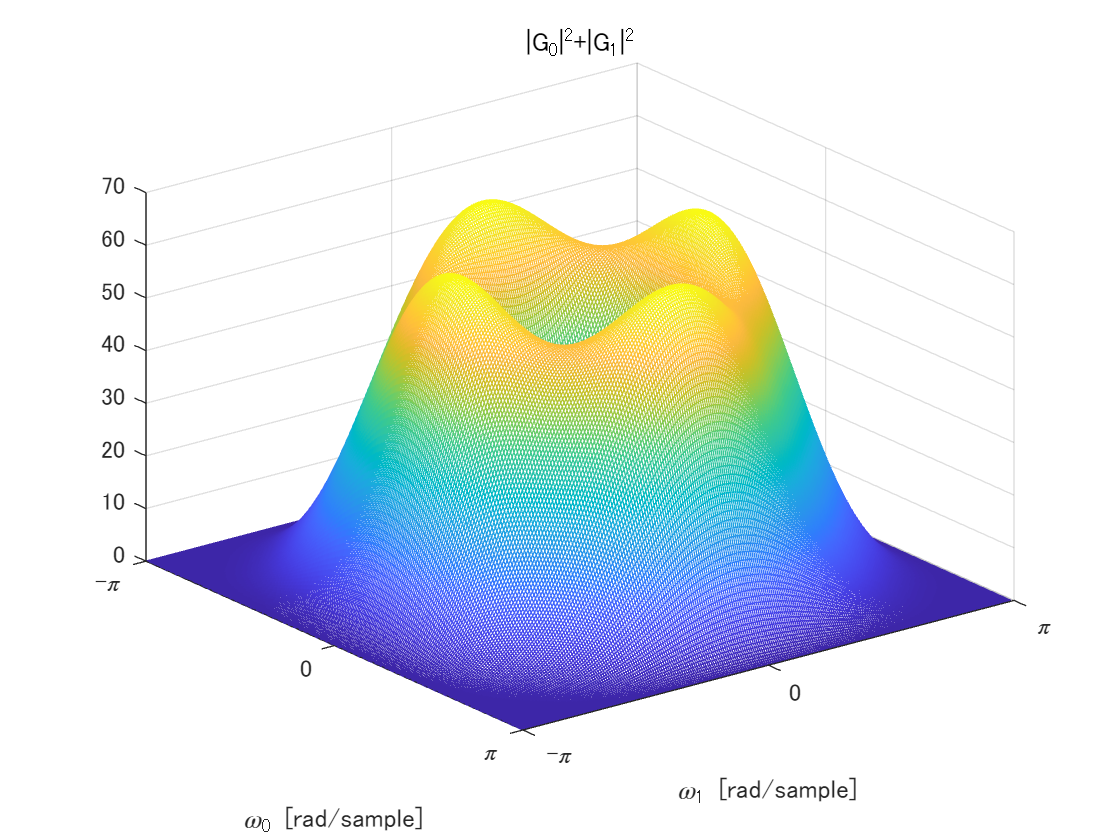

figure(7)
mesh(k1,k0,fftshift(GG))
ylabel('\omega_0 [rad/sample]')
xlabel('\omega_1 [rad/sample]')
title('|G_0|^2+|G_1|^2')
ax = gca;
ax.YDir = 'reverse';
ax.YLim = [-pi pi];
ax.XLim = [-pi pi];
ax.YTick = [-pi 0 pi];
ax.YTickLabel = { '-\pi', '0', '\pi'};
ax.XTick = [-pi 0 pi];
ax.XTickLabel = { '-\pi', '0', '\pi'};

### 画像再構成

(Image reconstuction)

零割を避けるために分母に EPS を加算 (Add EPS to the denominator to avoid dividing by zero.)

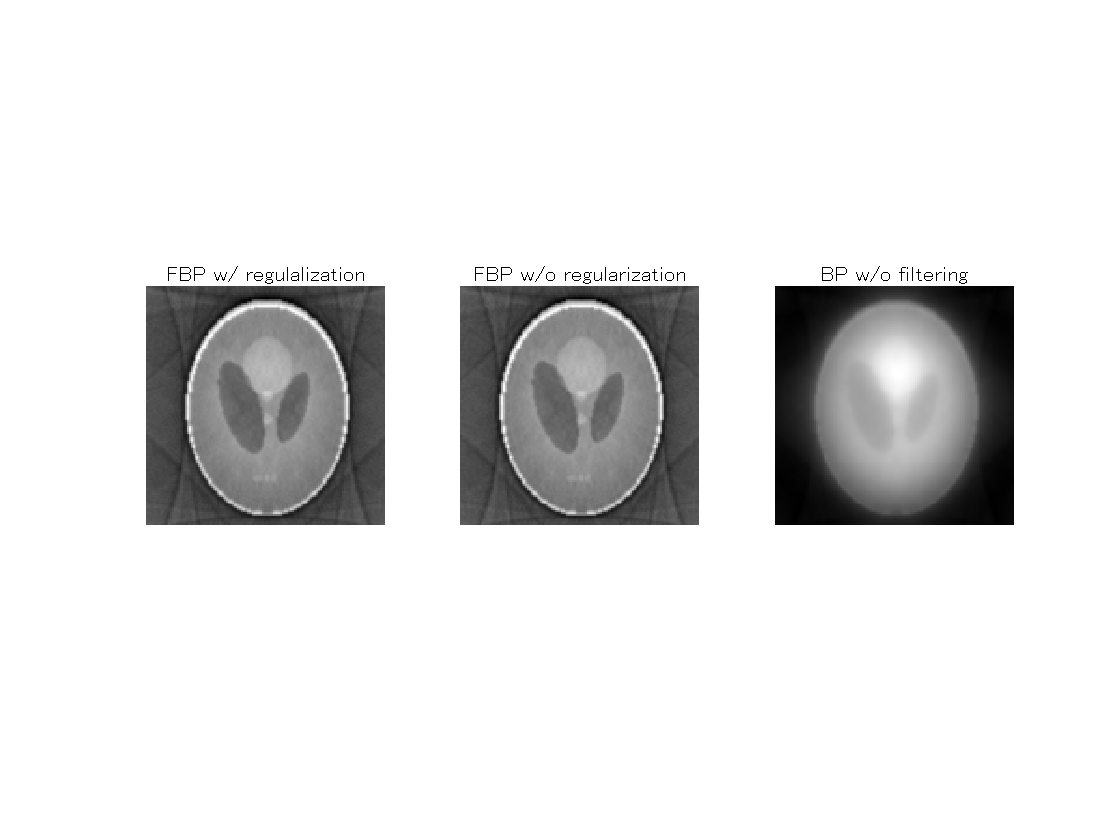

figure(8)
% FBP w/ regulalization
Ur = SR./(SS+lambda*LL+eps);
ur = circshift(real(ifft2(Ur)),size(u)/2);
ur = ur(1:size(u,1),1:size(u,2));
subplot(1,3,1)
imshow(ur,[])
title('FBP w/ regulalization')

% FBP w/o regulalization
Uo = SR./(SS+eps);
uo = circshift(real(ifft2(Uo)),size(u)/2);
uo = uo(1:size(u,1),1:size(u,2));
subplot(1,3,2)
imshow(uo,[])
title('FBP w/o regularization')

% BP w/o filtering
ub = circshift(real(ifft2(SR)),size(u)/2);
ub = ub(1:size(u,1),1:size(u,2));
subplot(1,3,3)
imshow(ub,[])
title('BP w/o filtering')

### IRADON関数

(Functon IRADON)

逆ラドン変換を行うMATLAB関数IRADONの利用例 (An example of using the MATLAB function IRADON to perform the inverse radon transformation)

Perform filtered backprojection.

I1 = iradon(r,thetaset);

Perform unfiltered backprojection.

I2 = iradon(r,thetaset,'linear','none');

Display the reconstructed images.

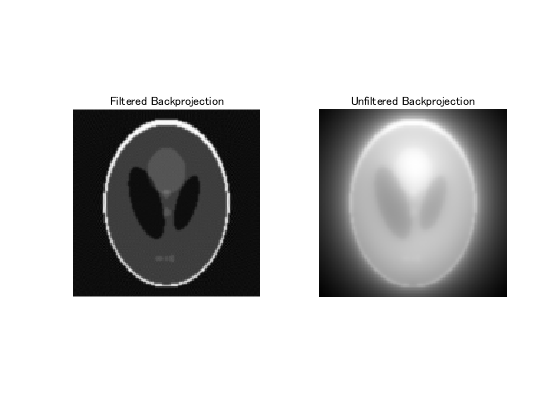

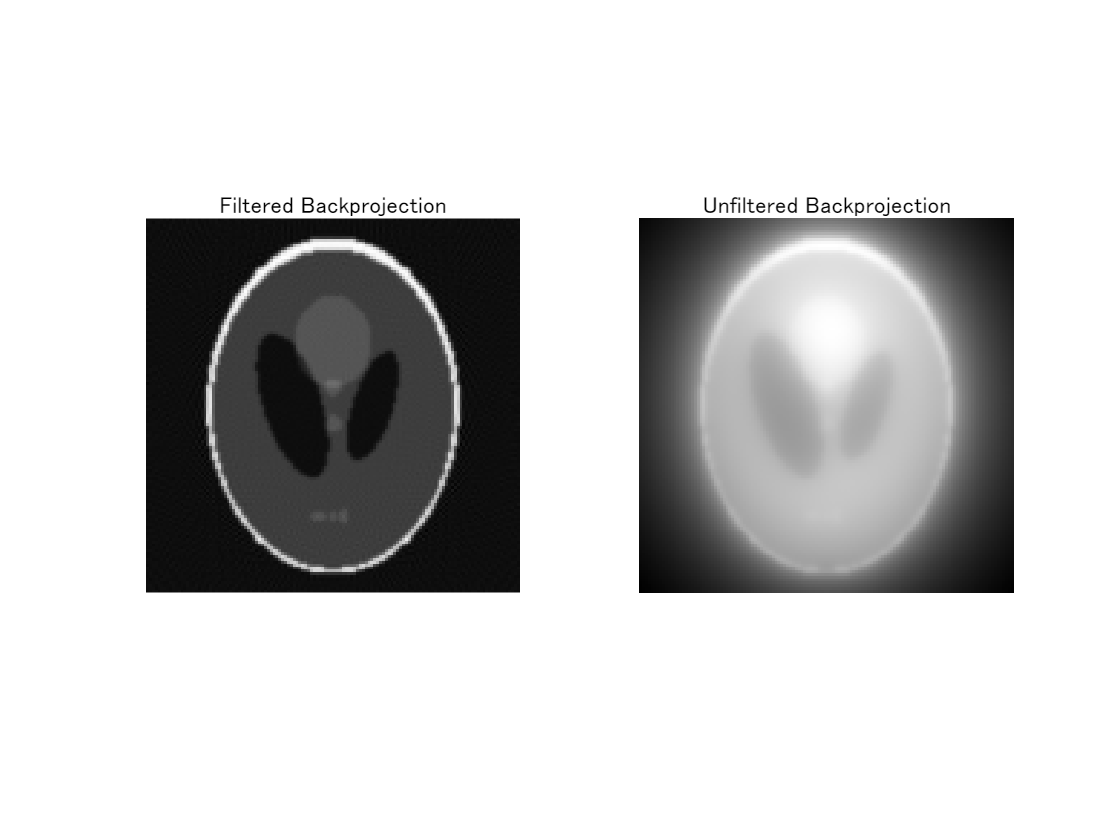

figure(9)
subplot(1,2,1)
imshow(I1,[])
title('Filtered Backprojection')
subplot(1,2,2)
imshow(I2,[])
title('Unfiltered Backprojection')

© Copyright, Shogo MURAMATSU, All rights reserved.